lambdaStart=importdata('lambda_start.csv');
lambdaDelta=importdata('lambda_delta.csv');
spectra=importdata('spectra.csv');
starNames=importdata('star_names.csv');


nObs=size(spectra,1);
nStars=size(starNames,1)

nStars = 7



lambdaEnd=lambdaStart+(nObs-1)*lambdaDelta;
lambda=(lambdaStart:lambdaDelta:lambdaEnd)';

s1=spectra(:,1);
[sHAa1,idx1]=min(s1);
lambdaHa1=lambda(idx1);
z1=(lambdaHa1/656.28)-1;
speed1=z1*299792.458;

s2=spectra(:,2);
[sHAa2,idx2]=min(s2);
lambdaHa2=lambda(idx2);
z2=(lambdaHa2/656.28)-1;
speed2=z2*299792.458;

s3=spectra(:,3);
[sHAa3,idx3]=min(s3);
lambdaHa3=lambda(idx3);
z3=(lambdaHa3/656.28)-1;
speed3=z3*299792.458;

s4=spectra(:,4);
[sHAa4,idx4]=min(s4);
lambdaHa4=lambda(idx4);
z4=(lambdaHa4/656.28)-1;
speed4=z4*299792.458;

s5=spectra(:,5);
[sHAa5,idx5]=min(s5);
lambdaHa5=lambda(idx5);
z5=(lambdaHa5/656.28)-1;
speed5=z5*299792.458;

s6=spectra(:,6);
[sHAa6,idx6]=min(s6);
lambdaHa=lambda(idx6);
z6=(lambdaHa/656.28)-1;
speed6=z6*299792.458;

s7=spectra(:,7);
[sHAa7,idx7]=min(s7);
lambdaHa7=lambda(idx7);
z7=(lambdaHa7/656.28)-1;
speed7=z7*299792.458;

speed=[speed1, speed2, speed3 ,speed4 ,speed5 ,speed6, speed7]'

speed =   -36.5445
 -100.4973
  -36.5445
   27.4083
   27.4083
  155.3139
 -228.4029



movaway=[starNames(4),starNames(5),starNames(6)]'

movaway = 3×1 cell array
    {'HD5211' }
    {'HD56030'}
    {'HD94028'}



fg1=figure

fg1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [441 379 560 420]
       Units: 'pixels'

  Show all properties


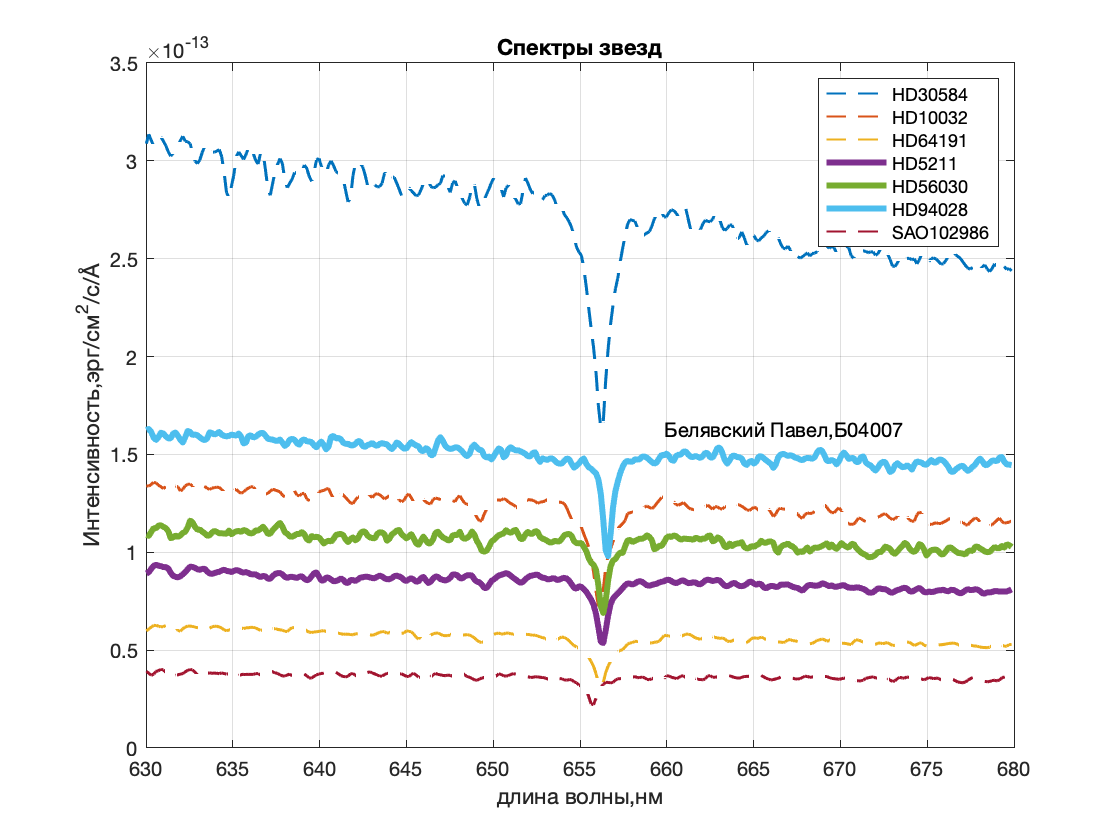

plot(lambda,s1,'--','LineWidth',1)
grid on
hold on 
plot(lambda,s2,'--','LineWidth',1)
plot(lambda,s3,'--','LineWidth',1)
plot(lambda,s4,'LineWidth',3)
plot(lambda,s5,'LineWidth',3)
plot(lambda,s6,'LineWidth',3)
plot(lambda,s7,'--','LineWidth',1)
xlabel('длина волны,нм')
ylabel(['Интенсивность,эрг/см^2/с/',char(197)])
title('Спектры звезд')
legend('HD30584','HD10032','HD64191','HD5211','HD56030','HD94028','SAO102986')
text(lambdaEnd-20,max(s6),'Белявский Павел,Б04007')
saveas(fg1,['Спектры.png']) 